# Correlation tryout

## Load the base wave file that is been send to the other components

Load the base signaling data and set it to 1kHz sample rate.

clc, clear;

filename = 'DATASET\pianosync.wav';
[y,Fs] = audioread(filename); % 8kHz sample 
%plot(y(1:2000, 1));
%title(".wav signal of 8kHz")

% pianosinc to 1kHz
Fs_new = 1000;
base_wave_1k = decimate(y(:,1)', 8);
figure;
%plot(base_wave_1k(1:250));
%title("Resampled signal to 1khz");

to bin

tresh = (abs(max(base_wave_1k)) - abs(min(base_wave_1k)))/2

tresh = -0.0052

base_wave_1kHz_bin(:) = (base_wave_1k(:)> tresh)

base_wave_1kHz_bin = 1×172252 logical array
   0   0   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1


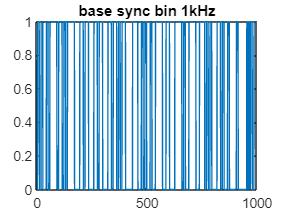

plot(base_wave_1kHz_bin(1:1000));
title("base sync bin 1kHz");

## Load the motion tracking data and resample to 1kHz

Add path of the function

clc, clear;
addpath OTHER\
% Add path of 
% use this function example  
% 'data = BinToQTM(elina3.Trajectories.Unidentified.Data, [637.1 457.7 193.6], [10 10 10]);'

raw_video_data = load("DATASET\elina3_nogapfilling.mat");
poi = [637.1 457.7 193.6];
tolerance_poi = [10 10 10];

video_capture_300 = double(QTMToBin(raw_video_data.elina3.Trajectories.Unidentified.Data, poi, tolerance_poi));
%plot(video_capture_300(1:300));
%title(" 300Hz sampled ");


%temp1 = interp(video_capture_300, 10); % bring it to 3000Hz
%video_capture_1k = decimate(temp1, 3); % bring it to 1000Hz -> 1kHz
video_capture_1k = resample(video_capture_300, 300, 1000);

% rat(resample/original) 

%plot(video_capture_1k(1:((300*10)/3))) % plot -> has some wiggles at the edges

to binar

tresh = (abs(max(video_capture_1k)) - abs(min(video_capture_1k)))/2

tresh = 0.4941

video_capture_1k_bin(:) = (video_capture_1k(:)> tresh)

video_capture_1k_bin = 1×324000 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1


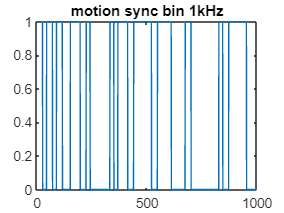

plot(video_capture_1k_bin(1:1000));
title("motion sync bin 1kHz");

## Load blood data

clc, clear;

raw_blood_data = load("DATASET\perfusion_and_sync_19-Dec-2023-11_15_20.mat");
raw_blood_data_sync_1k = raw_blood_data.fullDataSet(:, 1)';

%plot(raw_blood_data_sync_1k(1:400));


binar

tresh = (abs(max(raw_blood_data_sync_1k)) - abs(min(raw_blood_data_sync_1k)))/2

tresh = 1.4077

raw_blood_data_sync_1k_bin(:) = (raw_blood_data_sync_1k(:)> tresh)

raw_blood_data_sync_1k_bin = 1×175000 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0


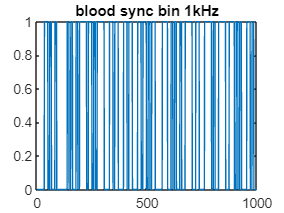

plot(raw_blood_data_sync_1k_bin(1:1000));
title("blood sync bin 1kHz");

## Load EMG data

clc, clear;
filename = 'DATASET\opensignals_000780589b3a_2023-12-19_11-12-23.txt';
txt = readmatrix(filename, 'Range', 4, 'Delimiter', '\t');

% https://nl.mathworks.com/help/matlab/ref/array2table.html#namevaluepairarguments
txt_table = array2table(txt,'VariableNames',{'nSeq','DI','CH1','CH2','CH3'});